# 3R Manipulator kinematics

## Reviewing 3R robot

clear
mdl_3link3d
R3

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, fastRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


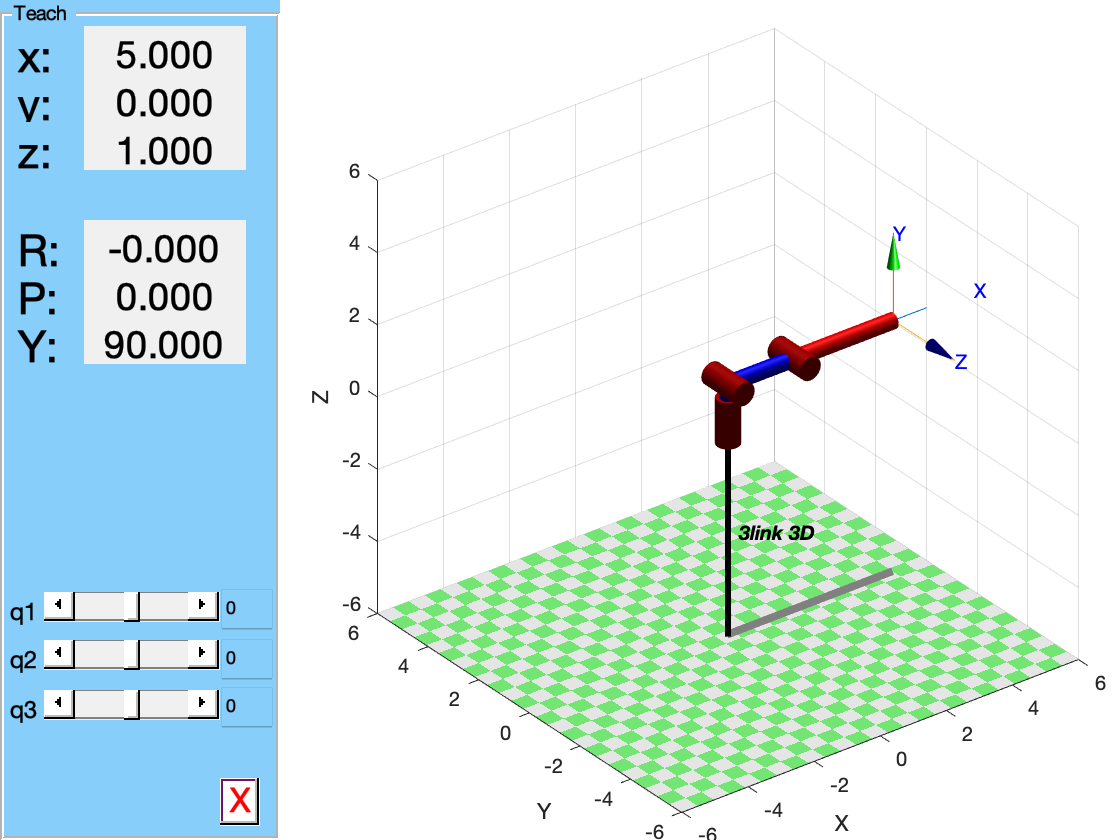

R3.plot([0 0 0])
R3.teach

## Forward Kinematics by hand

syms theta_1 theta_2 theta_3 L_0 L_1 L_2 real
FK_hand= simplify( ...
    transl(0,0,L_0)* ...
    trotz(theta_1)* ...
    trotx(pi/2)* ...
    trotz(theta_2)* ...
    transl(L_1,0,0)* ...
    trotz(theta_3)* ...
    transl(L_2,0,0) ...
)

$$FK\_hand = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{0}+L_{2}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{1}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{1}\,\cos\left(\theta_{2}\right) \end{array}$$

Numerical example

FK_3R=R3.fkine([pi/6 0 0 ])

 

FK_3R = 
    0.8660         0    0.5000      4.33
    0.5000         0   -0.8660       2.5
         0         1         0         1
         0         0         0         1


theta_1=atan2(FK_3R.t(2),FK_3R.t(1))

theta_1 = 0.5236

pi/6

ans = 0.5236

trotz(-theta_1)*FK_3R.T

ans =     1.0000   -0.0000    0.0000    5.0000
    0.0000    0.0000   -1.0000    0.0000
         0    1.0000    0.0000    1.0000
         0         0         0    1.0000


Notice that 

syms theta_1 theta_2 theta_3 L_1 L_2 real
FK= simplify(trotz(0)*trotx(pi/2)*trotz(theta_2)*transl(L_1,0,0)*trotz(theta_3)*transl(L_2,0,0))

$$FK = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right) & -\sin\left(\theta_{2}+\theta_{3}\right) & 0 & L_{2}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{1}\,\cos\left(\theta_{2}\right)\\ 0 & 0 & -1 & 0\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{2}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{1}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$